# Kubische Splineinterpolation

Wir betrachten die kubische Splineinterpolationsaufgabe auf dem Intervall $[0,1]$, mit  äquidistanten 

Stützstellen $x_j=j*h$, $j=0,\ldots,n$, $nh=1$:

                  $\text{Finde}~~S \in \mathbb{P}_{4,\tau}=\{\, g \in C^2([0,1])~|~g_{|[x_i,x_{i+1}]} \in \Pi_3,~i=0,\ldots, n-1\,\}$  so dass $S(x_j)=f(x_j),~~j=0,\ldots,n.$

Wir definieren Daten $f_j=f(x_j)$, $j=0,\ldots,n$:

f=[0.3; 3; 1.4; 0; 4; 0; 1; 2.0 ; 2.5; 0.6];
n=length(f)-1;
Knoten=linspace(0,1,n+1)';
plot(Knoten,f,'*');
hold on

Die Splineinterpolation und das Lagrange-Interpolationspolynom werden berechnet und auf einem äquidistanten Gitter mit Schrittweite $10^{-2}$ ausgewertet.

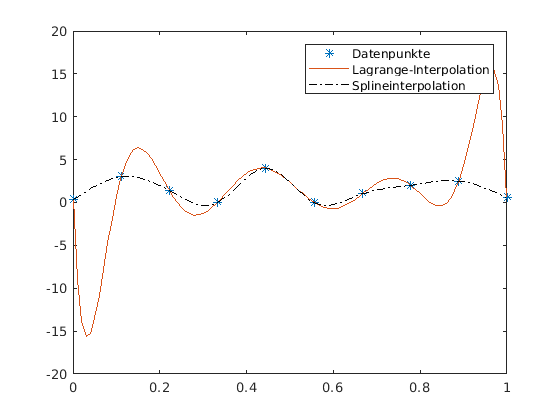

mplot=101;
x=linspace(0,1,mplot);
Lagrange=zeros(mplot,1);
Spline=zeros(mplot,1);
for i=1:mplot
    Lagrange(i)=lagrange(x(i),Knoten,f);
    Spline(i)=spline(x(i),f);
end
plot(x,Lagrange,'-', x,Spline,'k-.');
legend('Datenpunkte','Lagrange-Interpolation','Splineinterpolation');
hold off

# Aktivität: 

Variieren Sie die Daten$f(x_j)$ und beobachten Sie die Effekte.

function y=lagrange(x,Knoten,Daten)
% Diese Funktion wertet das Interpolationspolynom in der Lagrange-Darstellung an der Stelle x aus.
    m=length(Knoten);
    L=ones(m,1);
    for i=1:m
        for k=1:m
            if (i~=k)
                L(i)=L(i)*(x-Knoten(k))/(Knoten(i)-Knoten(k));
            end
        end
    end
    y=Daten'*L;
end

function y=spline(x,f)
% Diese Funktion wertet die kubische Splineinterpolation mit äquidistanten Stützstellen und Daten f an der Stelle x aus.
    n=length(f)-1; h=1/n;
    Knoten=(0:h:1)';
    A=full(gallery('tridiag',n-1,1,4,1));
    b=zeros(n-1,1);
    for i=1:n-1
        b(i)=f(i) - 2*f(i+1) + f(i+2);   
    end
    mt=A\(6/(h^2)*b);
    m=zeros(n+1,1); m(2:n)=mt;
    for j=1:n
        xleft=Knoten(j); xright=Knoten(j+1);
        if ((xleft<=x) && (x <=xright)) % x liegt im Teilintervall
            y= ((xright-x)^3*m(j) + (x-xleft)^3*m(j+1))/(6*h) ...
             + ((xright-x)*f(j) + (x-xleft)*f(j+1))/h - h*((xright-x)*m(j) + (x-xleft)*m(j+1))/6;
            return
        end
    end 
end